## TP2 - Analyse Numérique

Constanza Corentin

%%%%%%%%% INIT %%%%%%%%%%
v = 0.01;
N = 25;

%% Discretisation
h=1/(N+1);
dt = 1;
[Y,X]=meshgrid(0:h:1,0:h:1);
X=reshape(X,[(N+2)^2,1]);
Y=reshape(Y,[(N+2)^2,1]);

%% Création des matrices intermédiaire 
A1= v*-(1/h^2)*Laplace2d(N+2,N+2);
A = kron(eye(2),A1);
B11 = spdiags([-ones(N+1,1),ones(N+1,1)], [0,1], N+1, N+2);
B22 = spdiags([-ones(N+1,1),-ones(N+1,1)], [0,1], N+1, N+2);
B1 = (dt/(2*h)) * kron(B22,B11) ;
B2 = (dt/(2*h)) * kron(B11,B22);

f1 = zeros((N+2)^2,1);
f2 = -30 * ones((N+2)^2,1);
Zb = zeros((N+1)^2,1);

%% Assemblage
M = [A1,zeros( (N+2)^2),B1.'; zeros( (N+2)^2), A1, B2.'; B1, B2, zeros((N+1)^2) ];
b = [f1;f2;Zb];

%% Résolution du Système
sol = M\b;
u1 = sol(1:(N+2)^2,1);
u2 = sol(1+(N+2)^2:2*(N+2)^2,1);
p = sol(1+ 2*(N+2)^2:end ,1);

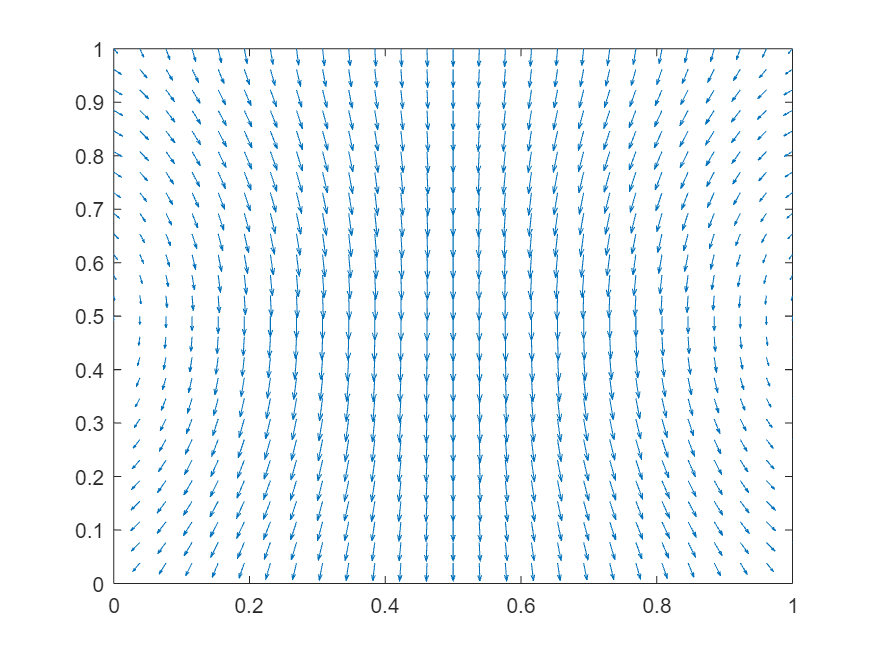

%% Affichage
quiver(X,Y,u1,u2)
axis([0 1 0 1])

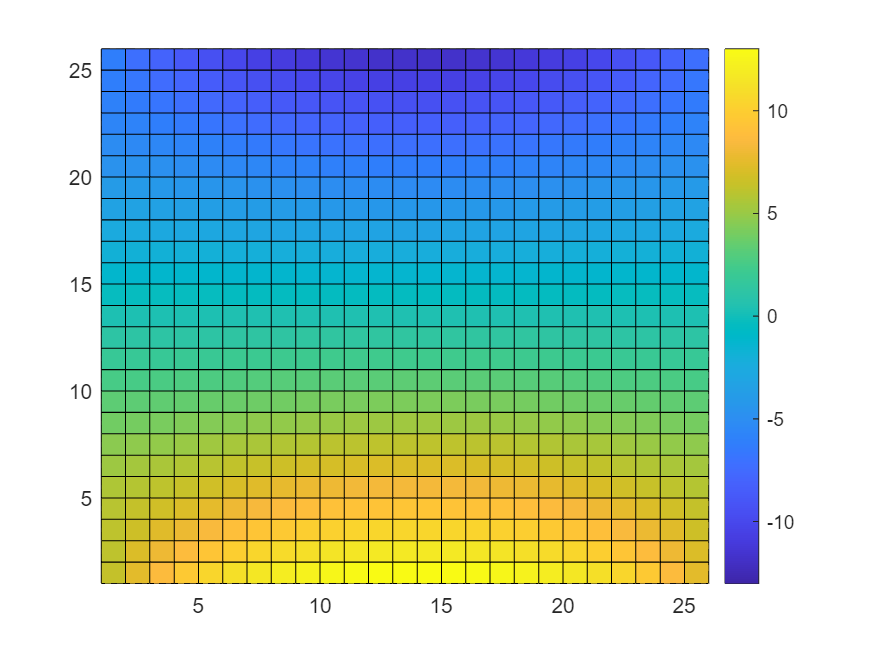

pcolor(reshape(p,N+1,N+1).')
colorbar

On peut voir que cette solution n'a aucun sens physique, ce qui est normal car nous avons pour l'instant pas pris en compte les conditions initiales. Nous allons donc pénaliser notre solution afin de les prendre en compte.

### Pénalisation du système : 

%% Création de la matrice de pénalisation
%% elle va nous permettre de "séléctionner" les éléments du bord
I1 = eye(N+2);
I2 = zeros(N+2);
I2(1,1) = 1;
I2(end, end)=1;

% Assemblage
I_ = kron(I2,I1) + kron(eye(N+2),I2) - kron(I2,I2);

%% Assemblage de la nouvelle matrice pénaliser
eps = 10^(7);
M_ = [A1 + eps*I_ ,zeros( (N+2)^2),B1.'; zeros( (N+2)^2), A1 + eps*I_, B2.'; B1, B2, zeros((N+1)^2) ];


u_temp1 = zeros( (N+2),1);
u_temp1(end,1) = 1;             %forme de la mat bloc (0 partout sauf pour le bloc du bord du haut)
u_temp2 = ones((N+2),1); 
u_temp1= kron( u_temp1, u_temp2);    
ubord1 =  15*u_temp1;
ubord2 = zeros((N+2)^2,1);

% assemblage du vecteur 2nd membre pénaliser
b_ = [f1 + eps*ubord1; f2 + eps*ubord2;Zb];

%% Résolution du système pénaliser
sol_ = M_\b_;
u1_ = sol_(1:(N+2)^2,1);
u2_ = sol_(1+(N+2)^2:2*(N+2)^2,1);
p_ = sol_(1+ 2*(N+2)^2:end ,1);

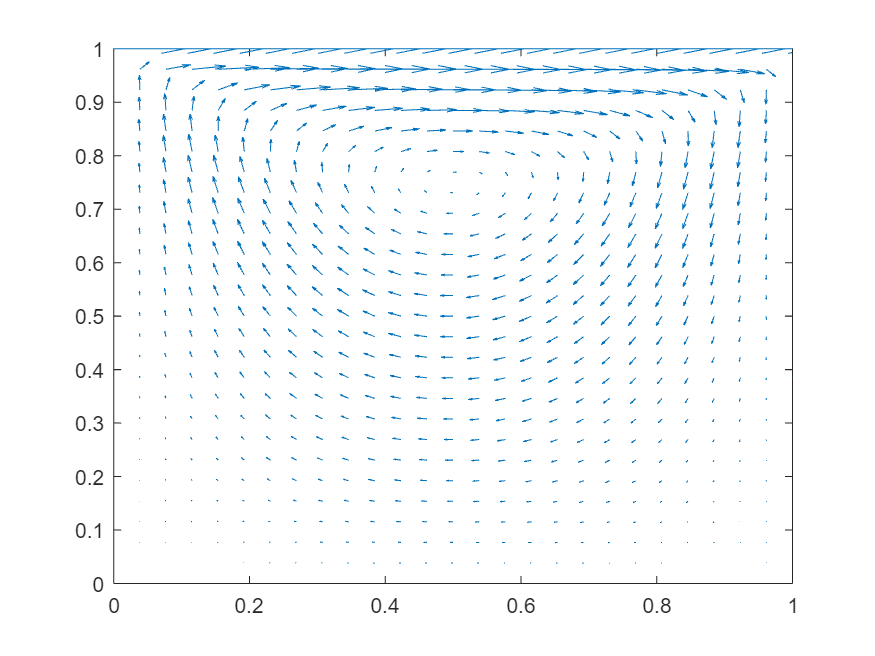

%%%%%% Affichage %%%%%%
quiver(X,Y,u1_,u2_,2)
axis([0 1 0 1])

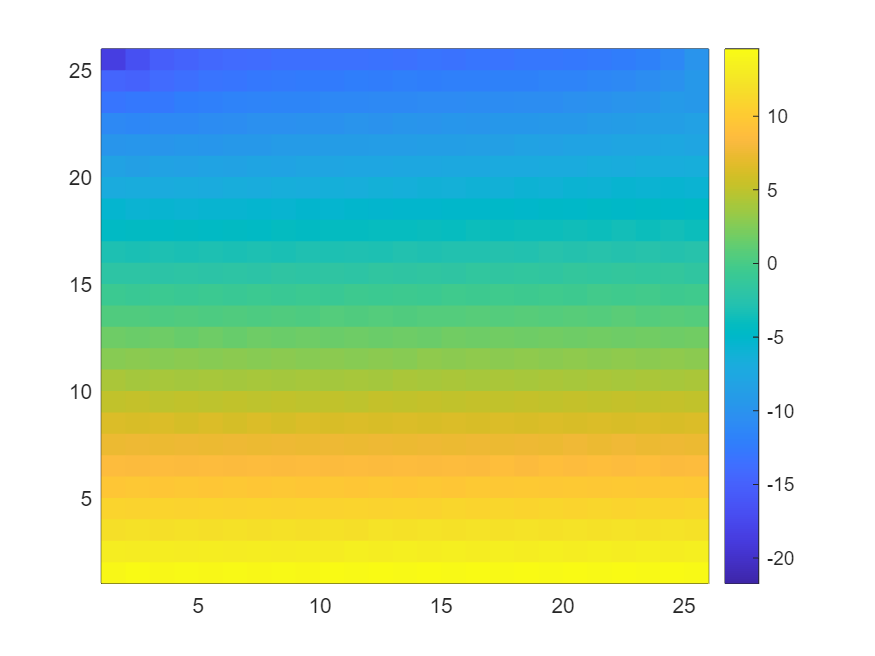

s=pcolor( (reshape(p_,N+1,N+1)).' );
set(s, 'EdgeColor', 'none');
colorbar

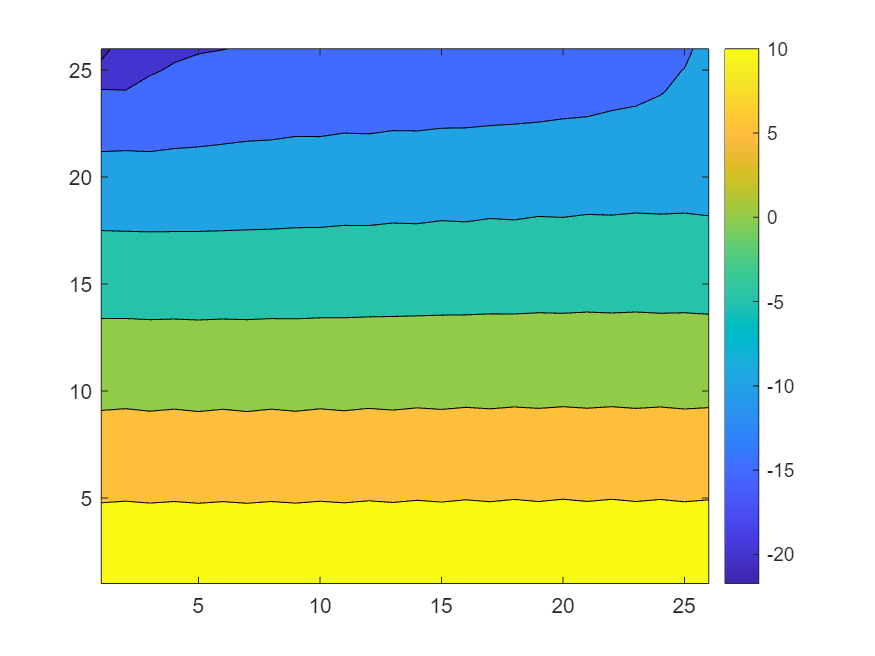

contourf((reshape(p_,N+1,N+1)).')
colorbar

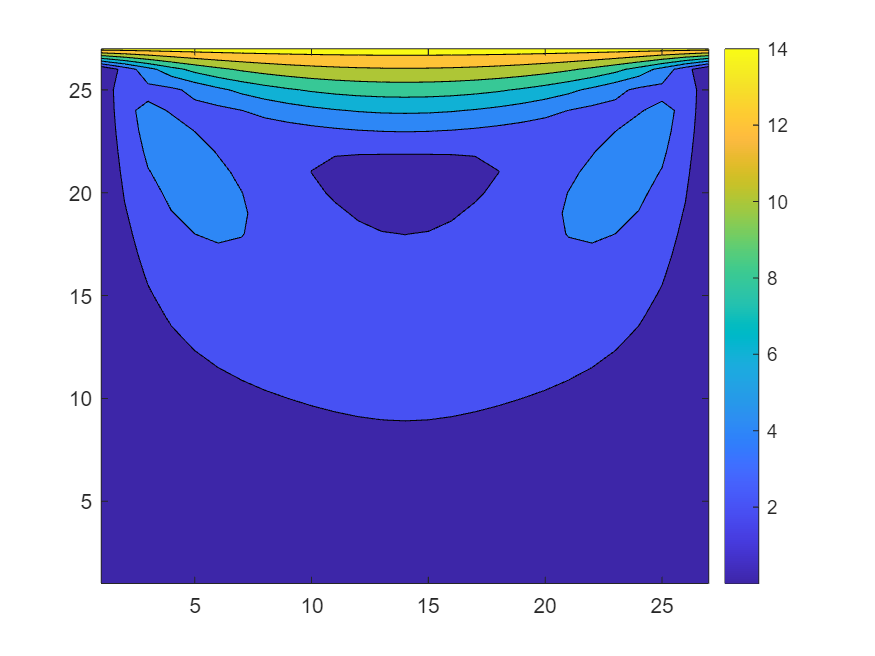

u = sqrt(u1_.^2 + u2_.^2);
contourf((reshape(u,N+2,N+2)).')
colorbar

## Algorithme de Schur : 

### Schur classique :

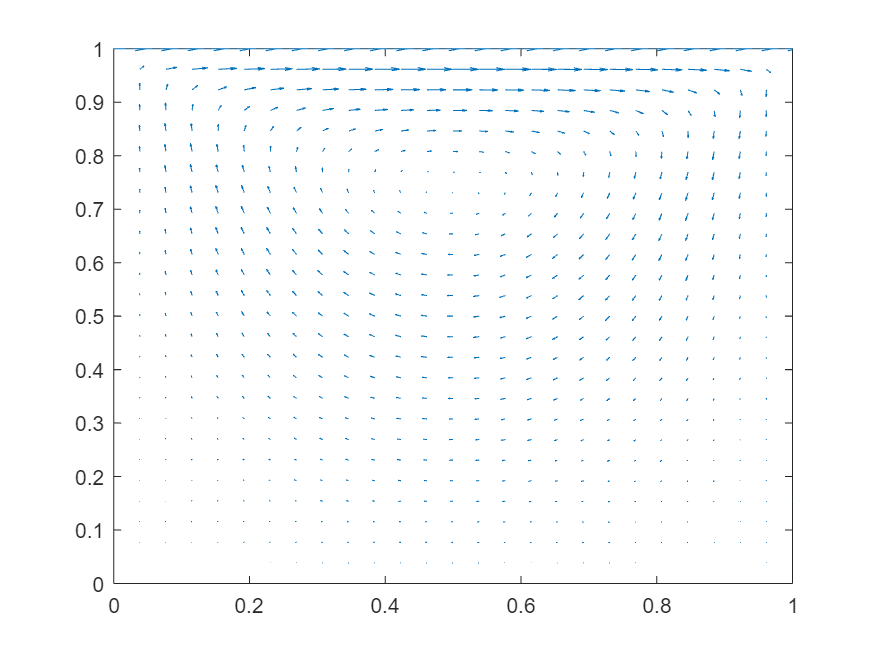

press = sparse((N+1)^2,1);
eps = 10e-6;
[sol_Schur,p_Schur] = Schur(M_,b_,N,press,1000,eps);
u1_Schur = sol_Schur(1:(N+2)^2,1);
u2_Schur = sol_Schur(1+(N+2)^2:2*(N+2)^2,1);

%%%%%% Affichage %%%%%

quiver(X,Y,u1_Schur,u2_Schur)
axis([0 1 0 1])

contourf((reshape(p_Schur,N+1,N+1)).')
colorbar

### Schur par bloc :

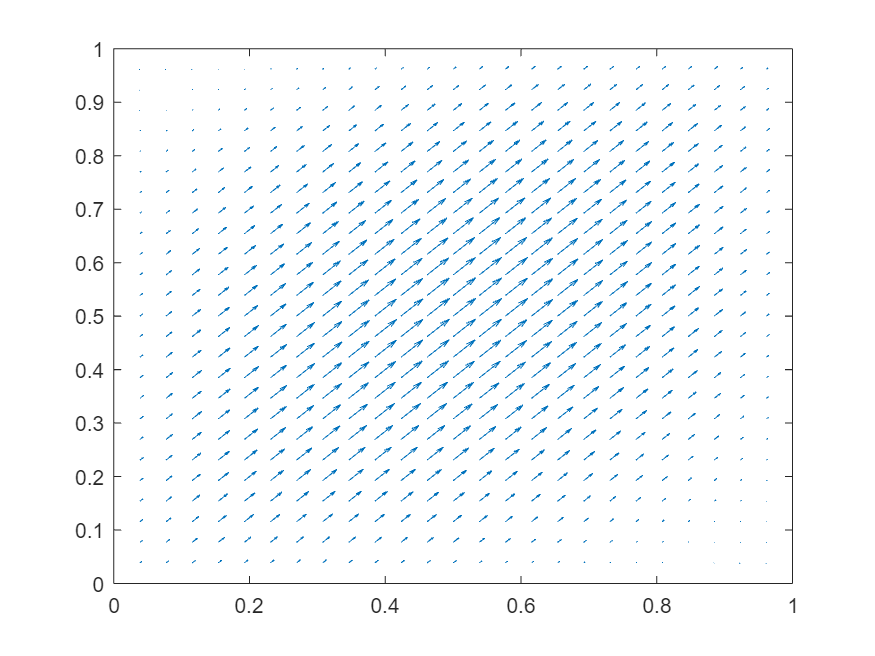

press = zeros((N+1)^2,1);
eps = 10e-8;
[sol_Schur_Bloc,p_Schur_Bloc] = Schur_Bloc(M_,b_,N,press,5000,eps);
u1_Schur_Bloc = sol_Schur_Bloc(1:(N+2)^2,1);
u2_Schur_Bloc = sol_Schur_Bloc(1+(N+2)^2:2*(N+2)^2,1);

%%%%%% Affichage %%%%%

quiver(X,Y,u1_Schur_Bloc,u2_Schur_Bloc)
axis([0 1 0 1])

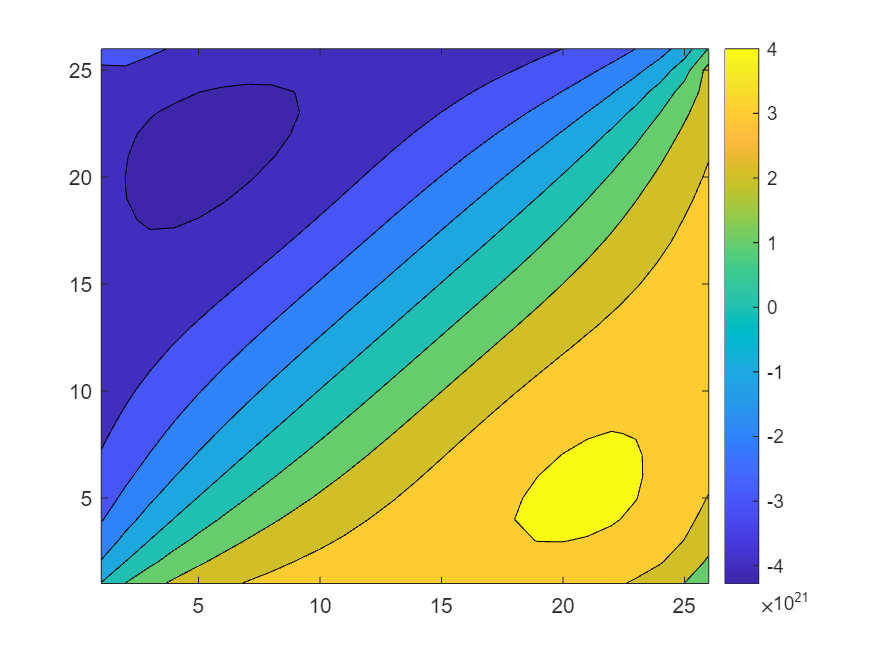

contourf((reshape(p_Schur_Bloc,N+1,N+1)).')
colorbar

### Shur approximé :

Afin de reduire les temps d'essayer de reduire les temps de calculs, nous allons utiliser la version approximé de l'algorithme de Schur. Cela consiste simplement à utiliser le un algorithme de gradient avec un nombre maximum d'itération afin d'avoir une approximation des résolutions des differents système.

press = sparse((N+1)^2,1);
eps = 10e-6;
tic;
[sol_Schur_Approx,p_Schur_Approx] = Schur_Approx(M_,b_,N,press,1000,eps,@Precond_SSOR);
toc

Elapsed time is 0.840483 seconds.


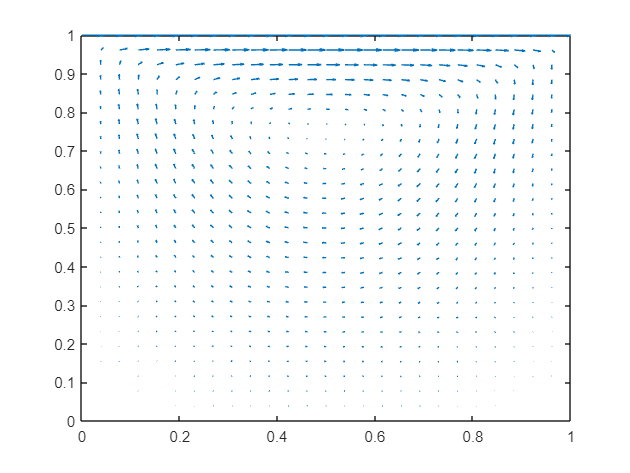

u1_Schur_Approx = sol_Schur_Approx(1:(N+2)^2,1);
u2_Schur_Approx = sol_Schur_Approx(1+(N+2)^2:2*(N+2)^2,1);

%%%%%% Affichage %%%%%
quiver(X,Y,u1_Schur_Approx,u2_Schur_Approx)
axis([0 1 0 1])

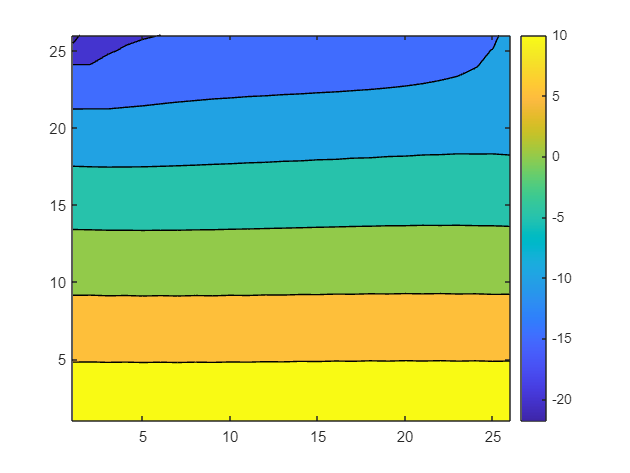

contourf((reshape(p_Schur_Approx,N+1,N+1)).')
colorbar

press = sparse((N+1)^2,1);
eps = 10e-6;
tic;
[sol_Schur_Approx,p_Schur_Approx] = Schur_Approx(M_,b_,N,press,1000,eps,@Precond_ILU);
toc

Elapsed time is 4.784557 seconds.


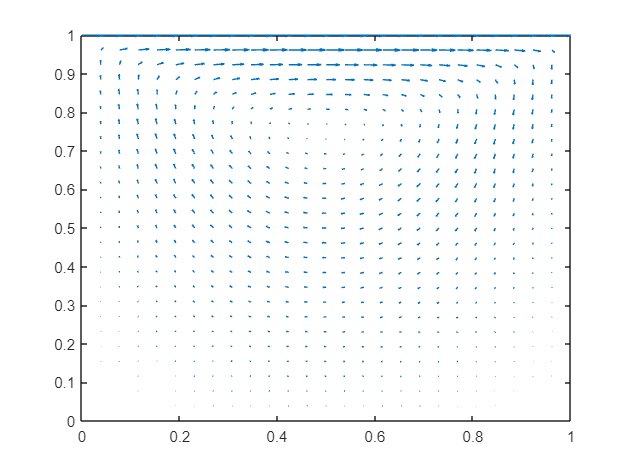

u1_Schur_Approx = sol_Schur_Approx(1:(N+2)^2,1);
u2_Schur_Approx = sol_Schur_Approx(1+(N+2)^2:2*(N+2)^2,1);

%%%%%% Affichage %%%%%
quiver(X,Y,u1_Schur_Approx,u2_Schur_Approx)
axis([0 1 0 1])

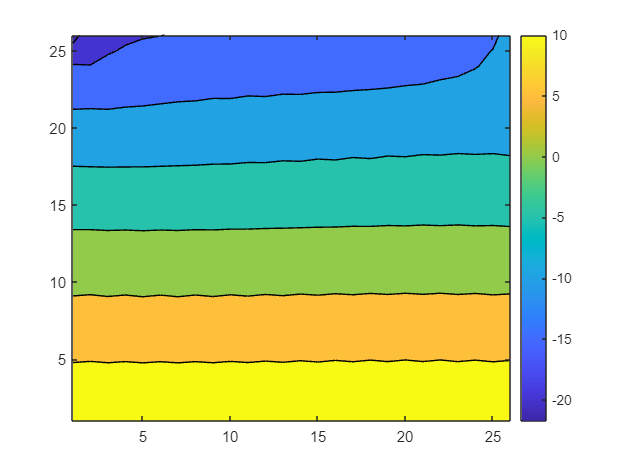

contourf((reshape(p_Schur_Approx,N+1,N+1)).')
colorbar

On peut voir qu'on obtient bien les resultats attendus.

## Comparaison des temps de calculs : 

Dans cette partie, nous allons comparer les temps de calculs des differents algos sur des système de plus en plus grands.

N = [1,5,10,25,50,75,100,125,150];
tps_umfpack = zeros(length(N),1);
tps_Schur = zeros(length(N),1);
tps_Schur_Bloc = zeros(length(N),1);
tps_Schur_Approx_GC = zeros(length(N),1);
tps_Schur_Approx_SSOR = zeros(length(N),1);
tps_Schur_Approx_ILU = zeros(length(N),1);

for i = 1:length(N)
    %discretisation
    h=1/(N(i)+1);
    dt = 1;
    [Y,X]=meshgrid(0:h:1,0:h:1);
    X=reshape(X,[(N(i)+2)^2,1]);
    Y=reshape(Y,[(N(i)+2)^2,1]);
    %Construction des A et B
    A1= v*-(1/h^2)*Laplace2d(N(i)+2,N(i)+2);
    A = kron(eye(2),A1);
    B11 = spdiags([-ones(N(i)+1,1),ones(N(i)+1,1)], [0,1], N(i)+1, N(i)+2);
    B22 = spdiags([-ones(N(i)+1,1),-ones(N(i)+1,1)], [0,1], N(i)+1, N(i)+2);
    B1 = (dt/(2*h)) * kron(B22,B11) ;
    B2 = (dt/(2*h)) * kron(B11,B22);
    %Construction de la pénalisation
    I1 = eye(N(i)+2);
    I2 = zeros(N(i)+2);
    I2(1,1) = 1;
    I2(end, end)=1;
    I_ = kron(I2,I1) + kron(eye(N(i)+2),I2) - kron(I2,I2);
    %Assemblage de M_
    eps = 10^(7);
    M_ = [A1 + eps*I_ ,zeros( (N(i)+2)^2),B1.'; zeros( (N(i)+2)^2), A1 + eps*I_, B2.'; B1, B2, zeros((N(i)+1)^2) ];
    %Construction de F
    f1 = zeros((N(i)+2)^2,1);
    f2 = -30 * ones((N(i)+2)^2,1);
    Zb = zeros((N(i)+1)^2,1);
    %Pénalisation
    u_temp1 = zeros( (N(i)+2),1);
    u_temp1(end,1) = 1;            
    u_temp2 = ones((N(i)+2),1);
    u_temp1= kron( u_temp1, u_temp2);    
    ubord1 =  15*u_temp1;
    ubord2 = zeros((N(i)+2)^2,1);
    %Assemblage de b_
    b_ = [f1 + eps*ubord1; f2 + eps*ubord2;Zb];

    % récuperation des temps de calculs :
    tic
    M_\b_;
    tps_umfpack(i)=toc;


    press = zeros((N(i)+1)^2,1);
    eps = 10e-8;

    tic
    Schur(M_,b_,N(i),press,1000,eps);
    tps_Schur(i) = toc;

    tic
    Schur_Approx(M_,b_,N(i),press,1000,eps,@Precond_ID);
    tps_Schur_Approx_GC(i) = toc;

    tic
    Schur_Approx(M_,b_,N(i),press,1000,eps,@Precond_SSOR);
    tps_Schur_Approx_SSOR(i) = toc;

    % tic
    % Schur_Approx(M_,b_,N(i),press,1000,eps,@Precond_ILU);
    % tps_Schur_Approx_ILU(i) = toc;


end

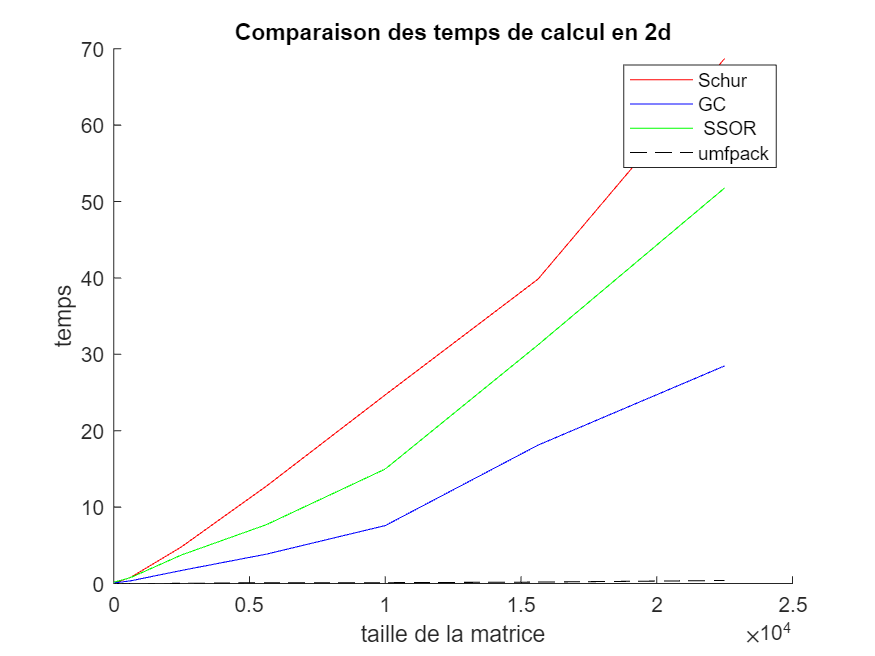

figure
xlabel("taille de la matrice")
ylabel("temps")
title("Comparaison des temps de calcul en 2d")
hold on
loglog(N.^2,tps_Schur, Color="red")
loglog(N.^2,tps_Schur_Approx_GC, Color="blue")
loglog(N.^2,tps_Schur_Approx_SSOR, Color="green")
%loglog(N.^2,tps_Schur_Approx_ILU, Color="yellow")
loglog(N.^2,tps_umfpack, Color="black", LineStyle='--')

legend(["Schur";"GC";" SSOR";"umfpack"])
hold off

On peut voir que l'operateur umfpack est toujours le plus performant (ce qui est attendu au vu des résultats du TP précedant, cela pourrait être differents en 3d cepandant). Il semble que dans les differentes variations de Schur la méthode approximer à l'aide du gradient conjuguer classique est la plus perfomantes, ce qui est logique car nous limitons le nombre d'iteration à 10. L'écart entre le GC et le GCP ( SSOR) se reduirait (et irait même jusqu'à s'inverser si l'on augmentait le nombre d'itération maximal. Cela vient du fait que tout le principe du préconditionnement répose sur le fait de faire le gros des calculs lors de la première iteration afin "d'optimiser" le système. 

Il n'y a pas ILU sur ce graphique car les temps de calculs de mon implémentation sont extremement long, malgres son très faible nombres d'itérations .(cf TP 1) 

## 3d : 

%%%%%%%%% INIT %%%%%%%%%%
v = 0.01;
N = 3;

%% Discretisation
h=1/(N+1);
dt = 1;
[Y,X,Z]=meshgrid(0:h:1,0:h:1,0:h:1);
X=reshape(X,[(N+2)^3,1]);
Y=reshape(Y,[(N+2)^3,1]);
Z=reshape(Y,[(N+2)^3,1]);
%% Création des matrices intermédiaire 
A1= v*-(1/h^2)*Laplace3d(N+2,N+2,N+2);
A = kron(eye(3),A1);

%La matrice B1 (resp. B2, B3) correspond à la dérivée par rapport à x (resp. y,z) de la pression.

B11 = spdiags([ones(N+1,1),zeros(N+1,1),-ones(N+1,1)], [0,1,2], N+1, N+2);

full(B11)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0



% B11 = spdiags([-ones(N+1,1),ones(N+1,1)], [0,1], N+1, N+2);
% B22 = spdiags([-ones(N+1,1),-ones(N+1,1)], [0,1], N+1, N+2);
% B1 = (dt/(2*h)) * kron(B22,B11) ;
% B2 = (dt/(2*h)) * kron(B11,B22);
% B3 =
% 
% f1 = zeros((N+2)^2,1);
% f2 = -30 * ones((N+2)^2,1);
% Zb = zeros((N+1)^2,1);
% 
% %% Assemblage
% M = [A1,zeros( (N+2)^2),B1.'; zeros( (N+2)^2), A1, B2.'; B1, B2, zeros((N+1)^2) ];
% b = [f1;f2;Zb];

## Annexes :

#### Fonction : 

function [M] = Laplace1d(n)
    e = ones(n, 1);
    M = spdiags([e -2*e e], -1:1, n, n);
end

function [M] = Laplace2d(n1, n2)
    M = kron(speye(n2), Laplace1d(n1)) + kron(Laplace1d(n2), speye(n1));
end

function [M] = Laplace3d(n1, n2, n3)
    M = kron(kron(speye(n3), speye(n2)), Laplace1d(n1)) ...
    + kron(kron(speye(n3), Laplace1d(n2)), speye(n1)) ...
    + kron(kron(Laplace1d(n3), speye(n2)), speye(n1));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x,y] = Schur(M,F,n,y,nmax,epsilon)

    A = M(1:2*(n+2)^2,1:2*(n+2)^2);
    B = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,1:2*(n+2)^2);
    Bt = M(1:2*(n+2)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);
    C = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);
    c = F(1:2*(n+2)^2);
    d = F(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);

    x=A\(c-Bt*y);
    r=d-C*y-B*x;
    dd=r;
    k=0;

    while (k<nmax) && (norm(M*cat(1,x,y)-F) > epsilon)
        w=A\(Bt*dd);
        z=C*dd-B*w;
        alpha=dot(r,dd)/dot(dd,z);
        y=y+alpha*dd;
        x=x-alpha*w;
        rr=r;
        r=r-alpha*z;
        beta=dot(r,r)/dot(rr,rr);
        dd=r+beta*dd;
        k=k+1;
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x,y] = Schur_Bloc(M,F,n,y,nmax,epsilon)
    
    A1 = M(1:(n+2)^2,1:(n+2)^2);
    A2 = M(1+(n+2)^2:2*(n+2)^2,1+(n+2)^2:2*(n+2)^2);

    B1 = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,1:(n+2)^2);
    B2 = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,1+(n+2)^2:2*(n+2)^2);
    B1t = M(1:(n+2)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);
    B2t = M(1+(n+2)^2:2*(n+2)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);

    f1 = F(1:(n+2)^2);
    f2 = F((n+2)^2+1:2*(n+2)^2);
    %f3 = F(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);

    u1 = A1\(f1-B1t*y);
    u2 = A2\(f2-B2t*y);
    
    r=B1*u1+B2*u2;
    dd=r;
    k=0;

    while (k<nmax) && (norm(M*vertcat([u1;u2],y)-F) > epsilon)
        w1=A1\(B2t*dd);
        w2=A2\(B2t*dd);
        z=B1*w1+B2*w2;
        alpha=dot(r,dd)/dot(dd,z);
        y=y+alpha*dd;
        u1=u1-alpha*w1;
        u2=u2-alpha*w2;
        rr=r;
        r=r-alpha*z;
        beta=dot(r,r)/dot(rr,rr);
        dd=r+beta*dd;
        k=k+1;
    end
    x = [u1;u2];
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x,y] = Schur_Approx(M,F,n,y,nmax,epsilon,Precond)

    A = M(1:2*(n+2)^2,1:2*(n+2)^2);
    B = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,1:2*(n+2)^2);
    Bt = M(1:2*(n+2)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);
    C = M(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2,2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);
    c = F(1:2*(n+2)^2);
    d = F(2*(n+2)^2+1:2*(n+2)^2+(n+1)^2);

    %x=A\(c-Bt*y);
    x0 = rand(2*(n+2)^2,1);
    x = GCP(A,x0,(c-Bt*y),Precond);

    r=d-C*y-B*x;
    dd=r;
    k=0;

    while (k<nmax) && (norm(M*cat(1,x,y)-F) > epsilon)
        %w=A\(Bt*dd);
        w = GCP(A,x0,(Bt*dd),Precond);
        z=C*dd-B*w;
        alpha=dot(r,dd)/dot(dd,z);
        y=y+alpha*dd;
        x=x-alpha*w;
        rr=r;
        r=r-alpha*z;
        beta=dot(r,r)/dot(rr,rr);
        dd=r+beta*dd;
        k=k+1;
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [sol] = GCP(A, x, b, Precond)
    tol = 10e-6;
    err = tol + 1;
    nb_iter = 0;
    r = b - A * x;
    z = Precond(A, r, true);
    d = z;
    
    res = [];
    iter = 0;
    while (err > tol)&&(nb_iter<10) %On met 10 iteration max
        xsave = x;
        rsave = r;
        zsave = z;
        
        alpha = dot(r, d) / dot(A * d, d);
        x = x + alpha * d;
        r = r - alpha * A * d;

        z = Precond(A, r, false);
        res = [res, r];
        beta = dot(r, z) / dot(rsave, zsave);
        d = z + beta * d;
        
        err = norm(xsave - x) / norm(xsave);
        nb_iter= nb_iter + 1;
        iter=iter +1;
    end
    sol = x;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Les fonctions suivante se trouvait dans des fichiers/scripts séparer lors
% de la compilation du notebook il se peut qu'il y faille les remettres
% dans des scripts séparer si lors d'une recompilation il y a des problèmes
% recontrés.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function z = Precond_SSOR(A, r, premier_passage)
    global L_SSOR U_SSOR D
    
    if premier_passage
        % On ne veut calculer la décomposition ILU qu'une fois : lors du premier passage.
        [L_SSOR, U_SSOR, D] = init_ssor(A);
    end
    z = U_SSOR \ (D * (L_SSOR \ r));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [L, U, D] = init_ssor(A)
    D = diag(diag(A));
    L = tril(A, -1);
    U = triu(A, 1);
    w_opt = 1.7; % recommendation du prof.
    
    L = (D + w_opt * L);
    U = (D + w_opt * U);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function z = Precond_ILU(A, r, premier_passage)
    global L_ILU U_ILU
    
    if premier_passage
        % On ne veut calculer la décomposition ILU qu'une fois : lors du premier passage. 
        [L_ILU, U_ILU] = init_ilu(A);
    end
    z = U_ILU \ (L_ILU \ r);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [L, U] = init_ilu(A)
    [L, U] = ilu(A, struct('type', 'ilutp', 'droptol', 1e-6));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y = Precond_ID(~,r,~)
    y=r;
end